clear all
clc
windowSize = 4096;
hopSize = 2048;
BPM = 138;
beats = 1/(BPM/60)

beats = 0.4348

quantification = beats/8 %double croche

quantification = 0.0543

wavFile = 'AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav'

wavFile = 'AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav'


test  = audioread(wavFile);
n = length(test);


audioTime = linspace(0, n/48000, n);
audioTime(length(audioTime))

ans = 8.2130

n = n/48000

n = 8.2130

%first methode
audio = miraudio(wavFile,'Normal');

Computing miraudio related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Computing mirsum related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
Elapsed time is 0.417018 seconds.


Computing mirfilterbank related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
 
filterBank is the Audio waveform related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav, of sampling rate 48000 Hz.


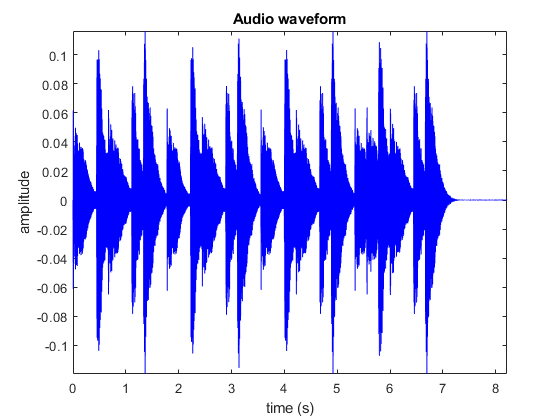

Its content is displayed in Figure 1.
 



filterBank = mirfilterbank(audio,'Gammatone','Channel',7)

Computing mirenvelope related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
 
enveloppe is the Differentiated envelope (half-wave rectified) related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav, of sampling rate 3000 Hz.


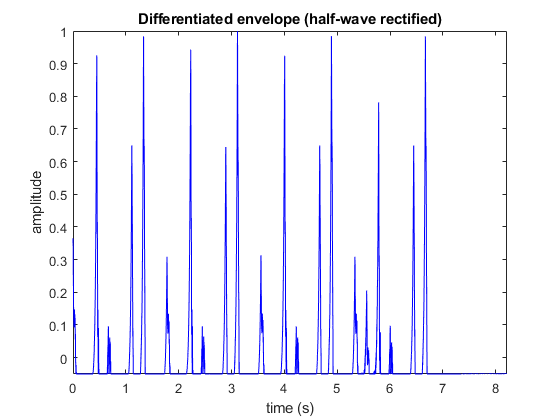

Its content is displayed in Figure 2.
 


%methode de suiveur envelope avec peak picking
enveloppe = mirenvelope(filterBank, 'FilterType', 'IIR','HalfwaveCenter','Diff','Normal','Center')

test = mirgetdata(enveloppe)

test =     0.3516
    0.3579
    0.3633
    0.3650
    0.3602
    0.3545
    0.3491
    0.3437
    0.3420
    0.3429


test2 = get(enveloppe,'Time')

test2 = 1×1 cell array
    {1×1 cell}


test2 = test2{1,1}{:,1}

test2 =          0
    0.0003
    0.0007
    0.0010
    0.0013
    0.0017
    0.0020
    0.0023
    0.0027
    0.0030


Computing mirpeaks related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav...
 
envelopepeaks is the Differentiated envelope (half-wave rectified) related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav, of sampling rate 3000 Hz.


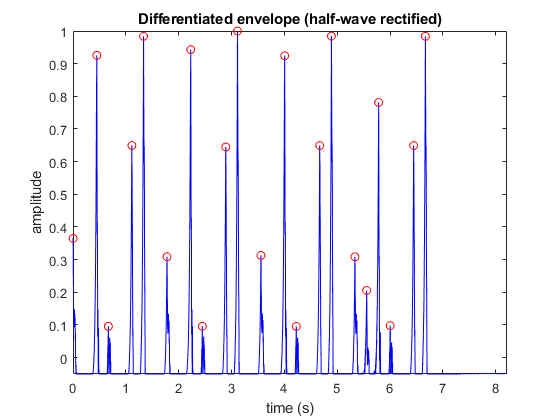

Its content is displayed in Figure 3.
 



envelopepeaks = mirpeaks(enveloppe,'Threshold',0.02,'Reso',quantification)

envelopedata =  mirgetdata(envelopepeaks)

envelopedata =     3.1126
    4.8904
    6.6682
    1.3349
    2.2281
    0.4503
    4.0059
    5.7836
    1.1135
    4.6690


envelopedataSort = sort(envelopedata(:,:,1))

envelopedataSort =     0.0009
    0.4503
    0.6696
    1.1135
    1.3349
    1.7787
    2.2281
    2.4472
    2.8912
    3.1126




nbrNotes = length(envelopedataSort)

nbrNotes = 21

 
sg is the Audio waveform related to AudioTest\BADSISTA_midi_BADSISTA_midi_bass_loop_agora_135_Dmin.wav, of sampling rate 48000 Hz.


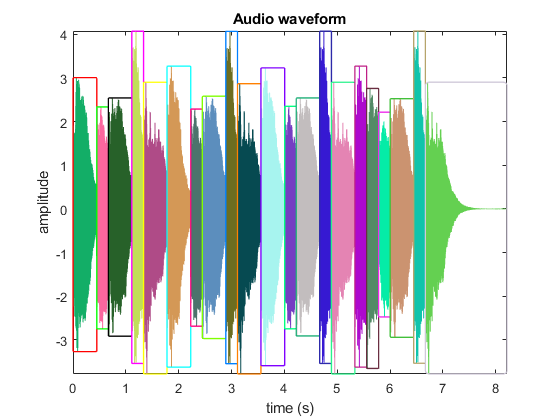

Its content is displayed in Figure 4.
 


sg = mirsegment(audio,envelopepeaks)


segmentPosition = get(sg,'FramePos')

segmentPosition = 1×1 cell array
    {1×22 cell}


posOfLastSg = segmentPosition{1}(size(segmentPosition{1},2))

posOfLastSg = 1×1 cell array
    {2×1 double}


posOfLastSg{1}(1)

ans = 6.6683

posOfLastSg{1}(2)

ans = 8.2129

audioTime

audioTime =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010



%store the segmented data
for i =1:nbrNotes
    
    
    if i == nbrNotes
        segmentedNotes{i} = miraudio(audio,'Extract' , posOfLastSg{1}(1),posOfLastSg{1}(2));
        duration(i) = 0.25;
    else
        segmentedNotes{i} = miraudio(audio,'Extract' ,envelopedataSort(i),envelopedataSort(i+1));
        duration(i) = envelopedataSort(i+1)-envelopedataSort(i);
    end
    spectrumNotes {i} = mirspectrum(segmentedNotes{i});
    test2 = mirspectrum(segmentedNotes{i},'Window','hamming','Min',0,'Max',3000);
    test = mirautocor(segmentedNotes{i},'Enhanced','max',0.0125);
    peak = mirpeaks(test,'Only','Total',1);
    data = mirgetdata(peak);
    peaksSpectrumNotes{i} = mirpeaks(spectrumNotes {i},'Only');
    
    spectrumData{i} = mirgetdata(peaksSpectrumNotes{i});
    %FundamentalFrequency(i) = abs(spectrumData{i}(1) -spectrumData{i}(2));
    midifreq (i,1) = round( hz2midi(1/data));
end


matrix(:,1) = envelopedataSort(:)/beats;
matrix(:,2) = duration/beats;
matrix(:,3) = 1.0;
matrix(:,4) = midifreq;
matrix(:,5) = 100;
matrix(:,6) = envelopedataSort(:);
matrix(:,7) = duration(:);


writemidi(matrix,'miditest.mid',BPM);